Load data

dataInputraw = load("pricevolumedata.mat") ;

dataInput = dataCleaningFcn_v2(dataInputraw)

dataInput = struct with fields:
    closepriceTT: [2930×665 timetable]
     highpriceTT: [2930×665 timetable]
      indexclean: [2930×6 timetable]
      lowpriceTT: [2930×665 timetable]
     openpriceTT: [2930×665 timetable]
        volumeTT: [2930×665 timetable]



openpriceTT     = dataInput.openpriceTT ;
highpriceTT     = dataInput.highpriceTT ;
lowpriceTT      = dataInput.lowpriceTT ;
closepriceTT    = dataInput.closepriceTT ;
volumeTT        = dataInput.volumeTT ;

clear dataInputraw

Define walk window dataset

% lookback upper bound
lookbackUB = 250;

% Number of step for training dataset
nstepTrain = 200;

% Number of step for testing dataset
nstepTest = 20;
% Number of step per walk dataset
nstepIST = lookbackUB + nstepTrain;
nstepOST = nstepTest;

% Number of walk for the whole walk forwad
nWalk = 36 ;
nstepWalk = nWalk*nstepOST + nstepIST;

% Number of rows in raw data
rowsData = size (closepriceTT,1) ;
% dataSet.openpriceTT = openpriceTT ;
% dataSet.highpriceTT = highpriceTT ;
% dataSet.lowpriceTT = lowpriceTT ;
% dataSet.closepriceTT = closepriceTT ;
% dataSet.volumeTT = volumeTT ;

Walk forward 

startTimer = tic ; 
nvars = 11 ; % number variables in optimParams to be optimizeds
optimParams = zeros(nWalk,nvars)    % Preallocate

optimParams =      0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 1

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 187.3483

optimParams_i =     63    54     5     1    10     8   121    25     5     3     8


optimParams =     63    54     5     1    10     8   121    25     5     3     8
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 2

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 172.0717

optimParams_i =     89   131     5     1    10    12   114    24     4     5     8


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 3

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 172.6050

optimParams_i =     98   191     5     1     8    12    71    29     3     4     4


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 4

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 202.7132

optimParams_i =    144   187     5     1    10     6   116    30     3     4     4


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 5

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 194.1290

optimParams_i =     98   148     5     6     8    12    77    20     3     5     6


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 6

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 180.0784

optimParams_i =     77   200     5     1    10    13    61    24     5     3     4


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 7

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 188.4478

optimParams_i =     69   142    25     5     9    13    90    23     4     3     8


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 8

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 150.1843

optimParams_i =    115   155     5     1    10     4   142    30     5     3     7


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0


i = 9

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 194.3354

optimParams_i =     85   196    21    10    10    13    83    26     5     3     8


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
     0     0     0     0     0     0     0     0     0     0     0


i = 10

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 195.3684

optimParams_i =     75    99     5     6     7    13    99    30     4     5     5


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 11

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 172.8218

optimParams_i =     83   141    23     4    10    13    84    22     5     3     7


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 12

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 227.4317

optimParams_i =     60   171     5     3     8    14    98    16     3     5     4


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 13

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 152.5006

optimParams_i =     96   128    34     3     5    11    80    28     5     5     8


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 14

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 261.7285

optimParams_i =     77    74    45     4     5    13    80    29     5     3     8


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 15

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 276.2245

optimParams_i =     61   136    17    10     8    10    98    29     5     5     7


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 16

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 217.3089

optimParams_i =    121    62    23     9     9    10    87    23     5     5     7


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 17

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 213.0212

optimParams_i =     60   145     5     1    10    15   121    27     5     1     3


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 18

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 186.6110

optimParams_i =    128   151     5     1    10    14   109    17     5     5     3


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 19

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 277.1789

optimParams_i =     60   200     6     1     8    15   110    16     4     5     4


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 20

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 238.6492

optimParams_i =    172   156     5     7    10    13    84    10     5     3     3


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 21

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 230.0725

optimParams_i =     73   178     5     7     8    14    84    27     5     5     4


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 22

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 225.6622

optimParams_i =     83   160     9     4     7    12    84    27     4     3     6


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 23

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 204.8674

optimParams_i =     60   168     7     4    10    13    73    24     4     3     5


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 24

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 253.0524

optimParams_i =     68   192     6     6     9    13    73    21     5     5     6


optimParams =     63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 25

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 192.7814

optimParams_i =     83   190     7     3     6    13    74    27     5     5     6


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 26

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 191.5419

optimParams_i = 1×11
    65   150     6     5     8    14    98    18     4     4     6


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 27

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 229.0988

optimParams_i = 1×11
   174   170    16     1    10    14    71    28     4     3     7


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 28

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 194.2751

optimParams_i = 1×11
    83   162     7     3    10    14    79    23     4     5     7


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 29

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 183.0874

optimParams_i = 1×11
   214   200     5     2     2     3   125    20     4     3     6


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 30

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 263.6577

optimParams_i = 1×11
   248   153     5     1     3     7   130    30     3     2     7


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 31

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 236.6659

optimParams_i = 1×11
   191   199     5     2     2     1   126    28     4     3     7


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 32

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 191.3302

optimParams_i = 1×11
   246   185     5     1     4     4   128    29     3     1     3


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 33

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 175.2328

optimParams_i = 1×11
   250   190    18     1     3     3   123    27     3     2     7


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 34

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 178.9472

optimParams_i = 1×11
   217   199     8     1     4     0   124    24     3     2     5


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 35

Objective or constraint function returned NaN.
surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 196.8754

optimParams_i = 1×11
   242   155     5     1     2     3   127    30     4     3     7


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5


i = 36

Objective or constraint function returned NaN.


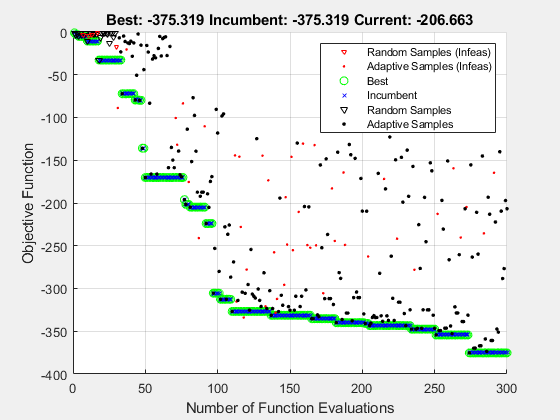

surrogateopt stopped because it exceeded the function evaluation limit set by 
'options.MaxFunctionEvaluations'.


endTime = 209.1879

optimParams_i = 1×11
   248   127     5     1     3     3   117    26     3     2     3


optimParams = 36×11
    63    54     5     1    10     8   121    25     5     3     8
    89   131     5     1    10    12   114    24     4     5     8
    98   191     5     1     8    12    71    29     3     4     4
   144   187     5     1    10     6   116    30     3     4     4
    98   148     5     6     8    12    77    20     3     5     6
    77   200     5     1    10    13    61    24     5     3     4
    69   142    25     5     9    13    90    23     4     3     8
   115   155     5     1    10     4   142    30     5     3     7
    85   196    21    10    10    13    83    26     5     3     8
    75    99     5     6     7    13    99    30     4     5     5



for i = 1:nWalk
    i
    % steps per walk
    OSTend_i = rowsData - nstepOST*(nWalk-i) ;
    OSTstart_i = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    % Define data set per walk
    % ISTdataSet
    ISTdataSet_i.openpriceTT    = openpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.highpriceTT    = highpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.lowpriceTT     = lowpriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.closepriceTT   = closepriceTT(ISTstart_i:ISTend_i,:) ;
    ISTdataSet_i.volumeTT       = volumeTT(ISTstart_i:ISTend_i,:) ;
    
    % Optimize optimParams per walk
    startOptimPoint = size(ISTdataSet_i.openpriceTT,1) - nstepTrain;
    
    optimParams_i = optimParamsFcn_v5 (ISTdataSet_i, startOptimPoint) 

    % Save optimparams per walk
    optimParams (i,:) = optimParams_i 
    

end


EndTimer = toc(startTimer)  

EndTimer = 7.4219e+03

timehours = EndTimer/(60*60)

timehours = 2.0616

Walk forward on optimizaed parameters in each walk

% Preallocate OSTportDailyRetTT 
OSTportDailyRetTT = openpriceTT (1,1) ;
OSTportDailyRetTT.Properties.VariableNames = "OSTportDailyRet" ;

% Preallocate netDailyRetperSymTT
OSTnetDailyRetperSymTT = closepriceTT (1,:) ;
sym = OSTnetDailyRetperSymTT.Properties.VariableNames ;
sym = eraseBetween (sym, 5,10) ;
OSTnetDailyRetperSymTT.Properties.VariableNames  = sym ;

% Preallocate tradingSignalTT 
OSTtradingSignalTT = OSTnetDailyRetperSymTT ;


for i = 1:nWalk
    
    % steps per walk
    OSTend_i    = rowsData - nstepOST*(nWalk-i) ;
    OSTstart_i  = OSTend_i - nstepOST + 1 ;
    ISTend_i    = OSTstart_i - 1 ;
    ISTstart_i  = ISTend_i - nstepIST + 1 ;
    
    % Params i
    paramsInput_i   = optimParams(i,:)     ;
    maxlookback     = max (paramsInput_i) ;
    
    % Define dataset
    % OSTdataSet
    OSTdataSet_i.openpriceTT    = openpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.highpriceTT    = highpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.lowpriceTT     = lowpriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.closepriceTT   = closepriceTT(OSTstart_i-maxlookback:OSTend_i,:) ;
    OSTdataSet_i.volumeTT       = volumeTT(OSTstart_i-maxlookback:OSTend_i,:) ;

    % Calculate portCumRet in OST
    tradingSignalTT_i = tradingSignalFcnVectorized_v1 (paramsInput_i, OSTdataSet_i) ;
    [portDailyRetTT_i, netDailyRetperSymTT_i] = tradingBacktestFcn_v2 (tradingSignalTT_i, OSTdataSet_i);
    
    % Concatenate tradingSignalTT
    OSTtradingSignalTT_i = tradingSignalTT_i(end-nstepOST+1:end,:) ;
    OSTtradingSignalTT = [OSTtradingSignalTT; OSTtradingSignalTT_i ] ;
    
    % Concatenate OSTportDailyRetTT
    OSTnetDailyRetperSymTT_i = netDailyRetperSymTT_i(end-nstepOST+1:end,:) ;
    OSTnetDailyRetperSymTT = [OSTnetDailyRetperSymTT; OSTnetDailyRetperSymTT_i ] ;
    
    % Concatenate OSTportDailyRetTT
    portDailyRetTT_i.Properties.VariableNames = OSTportDailyRetTT.Properties.VariableNames  ;
    OSTportDailyRetTT_i = portDailyRetTT_i(end-nstepOST+1:end,:) ;
    OSTportDailyRetTT = [OSTportDailyRetTT; OSTportDailyRetTT_i]  ;
   
end

OSTtradingSignalTT (1,:)       = []

OSTtradingSignalTT = 720×665 timetable
       Time       AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX    <

OSTnetDailyRetperSymTT (1,:)   = []

OSTnetDailyRetperSymTT = 720×665 timetable
       Time       AALI    ABBA    ABDA    ABMM    ACES    ACST    ADES    ADHI    ADMF    ADMG    ADRO    AGAR    AGII    AGRO    AGRS    AHAP    AIMS    AISA    AKKU    AKPI    AKRA    AKSI    ALDO    ALKA    ALMI    ALTO    AMAG    AMAN    AMAR    AMFG    AMIN    AMOR    AMRT    ANDI    ANJT    ANTM    APEX 

OSTportDailyRetTT (1,:)     = []

OSTportDailyRetTT = 720×1 timetable
       Time       OSTportDailyRet
    __________    _______________

    2018-11-30       -0.039772   
    2018-12-03         0.01724   
    2018-12-04       -0.025777   
    2018-12-05       -0.011313   
    2018-12-06       -0.027184   
    2018-12-07        0.021038   
    2018-12-10      -0.0097717   
    2018-12-11       -0.061331   
    2018-12-12        0.029494   
    2018-12-13        0.031915   
    2018-12-14        0.010241   
    2018-12-17       0.0027441   
    2018-12-18        0.012024   
    2018-12-19       -0.027967   
    2018-12-20       0.0032489   
    2018-12-21       -0.046489   


Analyze the results

walk_i = 1

walkStart_i = 1

walkEnd_i = 20

walk_i = 2

walkStart_i = 21

walkEnd_i = 40

walk_i = 3

walkStart_i = 41

walkEnd_i = 60

walk_i = 4

walkStart_i = 61

walkEnd_i = 80

walk_i = 5

walkStart_i = 81

walkEnd_i = 100

walk_i = 6

walkStart_i = 101

walkEnd_i = 120

walk_i = 7

walkStart_i = 121

walkEnd_i = 140

walk_i = 8

walkStart_i = 141

walkEnd_i = 160

walk_i = 9

walkStart_i = 161

walkEnd_i = 180

walk_i = 10

walkStart_i = 181

walkEnd_i = 200

walk_i = 11

walkStart_i = 201

walkEnd_i = 220

walk_i = 12

walkStart_i = 221

walkEnd_i = 240

walk_i = 13

walkStart_i = 241

walkEnd_i = 260

walk_i = 14

walkStart_i = 261

walkEnd_i = 280

walk_i = 15

walkStart_i = 281

walkEnd_i = 300

walk_i = 16

walkStart_i = 301

walkEnd_i = 320

walk_i = 17

walkStart_i = 321

walkEnd_i = 340

walk_i = 18

walkStart_i = 341

walkEnd_i = 360

walk_i = 19

walkStart_i = 361

walkEnd_i = 380

walk_i = 20

walkStart_i = 381

walkEnd_i = 400

walk_i = 21

walkStart_i = 401

walkEnd_i = 420

walk_i = 22

walkStart_i = 421

walkEnd_i = 440

walk_i = 23

walkStart_i = 441

walkEnd_i = 460

walk_i = 24

walkStart_i = 461

walkEnd_i = 480

walk_i = 25

walkStart_i = 481

walkEnd_i = 500

walk_i = 26

walkStart_i = 501

walkEnd_i = 520

walk_i = 27

walkStart_i = 521

walkEnd_i = 540

walk_i = 28

walkStart_i = 541

walkEnd_i = 560

walk_i = 29

walkStart_i = 561

walkEnd_i = 580

walk_i = 30

walkStart_i = 581

walkEnd_i = 600

walk_i = 31

walkStart_i = 601

walkEnd_i = 620

walk_i = 32

walkStart_i = 621

walkEnd_i = 640

walk_i = 33

walkStart_i = 641

walkEnd_i = 660

walk_i = 34

walkStart_i = 661

walkEnd_i = 680

walk_i = 35

walkStart_i = 681

walkEnd_i = 700

walk_i = 36

walkStart_i = 701

walkEnd_i = 720

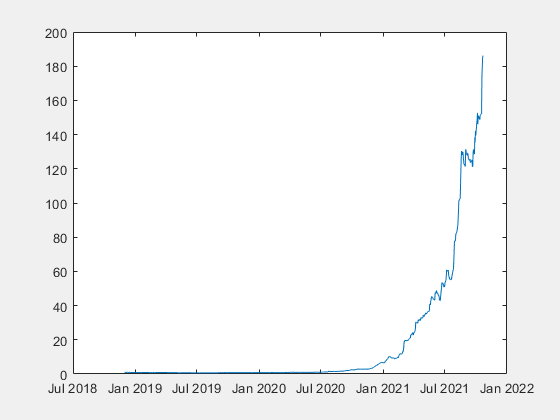

% Plot animated chart with pause or drawnow function
% Plot portCumRetTT    
% Plot animated chart with pause or drawnow function
for i = 1:nWalk
%     i = 2
    walk_i = i 

    walkStart_i = 1+ nstepOST*(i-1)
    walkEnd_i = walkStart_i + nstepOST-1
    OSTportDailyRetTT_i = OSTportDailyRetTT(1:walkEnd_i, :);
    
    OSTportCumRetTT = ret2tick (OSTportDailyRetTT_i) ;

%     semilogy(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
    plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)
    drawnow 
    pause(2);

end

Statistics

% OSTportCumRetTT = ret2tick (OSTportDailyRetTT) ;
% 
% plot(OSTportCumRetTT.Time, OSTportCumRetTT.Variables)

% CAGR
timeVar = OSTportCumRetTT.Time ;
OSTportCumRet = OSTportCumRetTT.Variables ;
OSTportCumRetEnd = OSTportCumRet(end,:)

OSTportCumRetEnd = 186.1277

nYear = yearfrac (timeVar(1,:), timeVar(end,:))

nYear = 2.8959

CAGR = ((OSTportCumRet (end,:) / OSTportCumRet (1,:))^(1/nYear))-1

CAGR = 5.1644


% Drawdown
[MDD,MaxDDIndex] = maxdrawdown(OSTportCumRetTT.Variables) ;
MaxDD = MDD 

MaxDD = 0.3518

drawDownTime = timeVar(MaxDDIndex)

drawDownTime = 2×1 datetime array
   2018-12-03
   2019-08-02


Number signal daily

nDailySignal = sum (OSTtradingSignalTT.Variables,2) ;

nDailySignal = 720×1
     5
     2
     5
     5
     7
     5
     4
     6
     5
     8


nDailySignalTT = OSTportCumRetTT ;

nDailySignalTT = 720×1 timetable
       Time       OSTportDailyRet
    __________    _______________

    2018-11-30        0.96023    
    2018-12-03        0.97678    
    2018-12-04         0.9516    
    2018-12-05        0.94084    
    2018-12-06        0.91526    
    2018-12-07        0.93452    
    2018-12-10        0.92539    
    2018-12-11        0.86863    
    2018-12-12        0.89425    
    2018-12-13        0.92279    
    2018-12-14        0.93224    
    2018-12-17         0.9348    
    2018-12-18        0.94604    
    2018-12-19        0.91958    
    2018-12-20        0.92257    
    2018-12-21        0.87968    


nDailySignalTT.Variables = nDailySignal ;

nDailySignalTT = 720×1 timetable
       Time       OSTportDailyRet
    __________    _______________

    2018-11-30           5       
    2018-12-03           2       
    2018-12-04           5       
    2018-12-05           5       
    2018-12-06           7       
    2018-12-07           5       
    2018-12-10           4       
    2018-12-11           6       
    2018-12-12           5       
    2018-12-13           8       
    2018-12-14           7       
    2018-12-17           6       
    2018-12-18           6       
    2018-12-19           4       
    2018-12-20           5       
    2018-12-21           2       


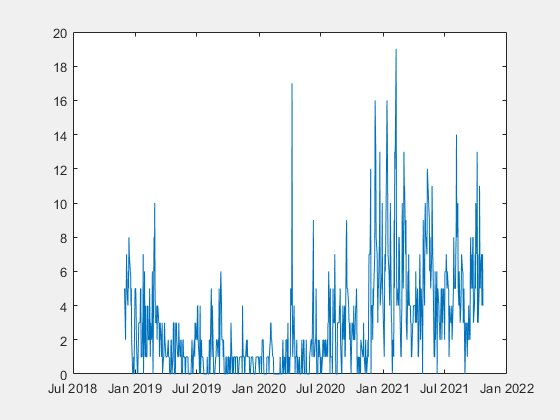


% plot daily signal
plot(nDailySignalTT.Time , nDailySignalTT.Variables )

Rank symbol based on cumulative return

symRank = rankSymbolsFcn (OSTnetDailyRetperSymTT)

symRank = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'FIRE'}       {[1.4497]}    
    {'BNBA'}       {[1.3664]}    
    {'BOLA'}       {[1.3051]}    
    {'INAF'}       {[1.2734]}    
    {'ZBRA'}       {[1.2701]}    
    {'KAEF'}       {[1.2246]}    
    {'MPPA'}       {[1.2082]}    
    {'BRIS'}       {[1.1827]}    
    {'IATA'}       {[1.1797]}    
    {'LMAS'}       {[1.1703]}    
    {'BABP'}       {[1.1619]}    
    {'REAL'}       {[1.1342]}    
    {'AGRO'}       {[1.1250]}    
    {'IPTV'}       {[1.1201]}    
    {'MLPL'}       {[1.1194]}    
    {'BKSW'}       {[1.1134]}    


symRank = 665×2 table
     symbol     Cumulative Return
    ________    _________________

    {'FIRE'}       {[1.4497]}    
    {'BNBA'}       {[1.3664]}    
    {'BOLA'}       {[1.3051]}    
    {'INAF'}       {[1.2734]}    
    {'ZBRA'}       {[1.2701]}    
    {'KAEF'}       {[1.2246]}    
    {'MPPA'}       {[1.2082]}    
    {'BRIS'}       {[1.1827]}    
    {'IATA'}       {[1.1797]}    
    {'LMAS'}       {[1.1703]}    
    {'BABP'}       {[1.1619]}    
    {'REAL'}       {[1.1342]}    
    {'AGRO'}       {[1.1250]}    
    {'IPTV'}       {[1.1201]}    
    {'MLPL'}       {[1.1194]}    
    {'BKSW'}       {[1.1134]}    


Discretionary

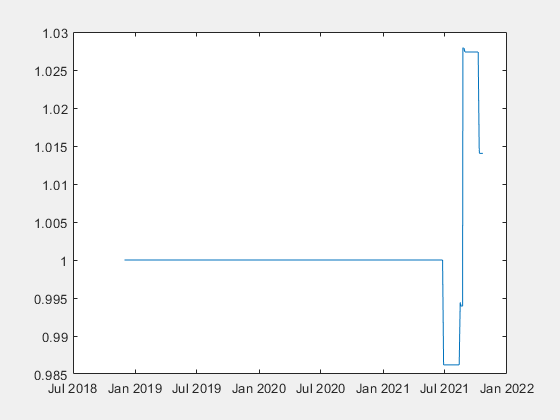

OSTCumRetperSymTT = ret2tick(OSTnetDailyRetperSymTT) ;

plot(OSTCumRetperSymTT.Time, OSTCumRetperSymTT.TECH)

Save optimParams to matfile

% Save optimParams to matfile
optimParams_filename = "optimParams.mat";
save (optimParams_filename , "optimParams") 
